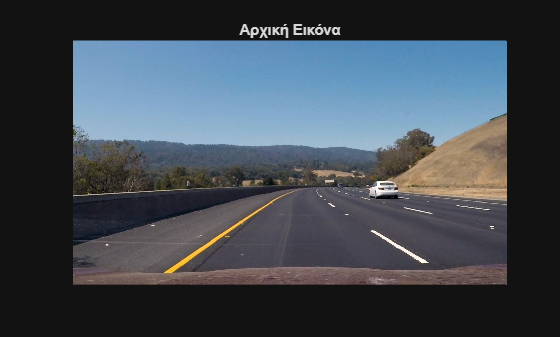

%% Ανίχνευση λωρίδων κυκλοφορίας και περιοχής δρόμου σε εικόνες οδήγησης
% Αρχικοποίηση Workspace
clear; clc; close all;

% Προσθήκη του υποφακέλου με τις εικόνες στο path του MATLAB
addpath('images'); 

%% 1. Φόρτωση Εικόνας Δοκιμής
% Μπορείς να αλλάξεις το όνομα για να δοκιμάσεις τις υπόλοιπες εικόνες
% (π.χ. 'solidYellowCurve.jpg', 'test1.jpg' κ.λπ.)
image_filename = 'test3.jpg'; 
img = imread(image_filename);

% Εμφάνιση αρχικής εικόνας
figure;
imshow(img);
title('Αρχική Εικόνα');

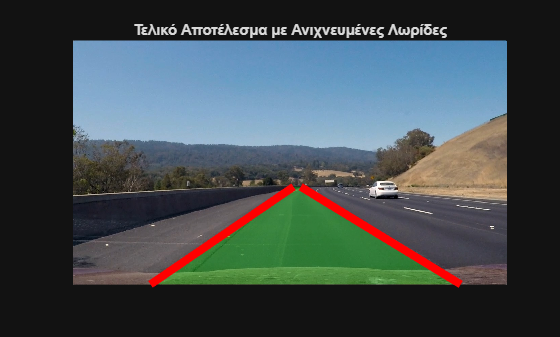


%% 2. Εκτέλεση του Pipeline Ανίχνευσης Λωρίδων
% Καλούμε την κύρια συνάρτηση 
final_image = lane_detection_pipeline(img);
title('Τελικό Αποτέλεσμα με Ανιχνευμένες Λωρίδες');

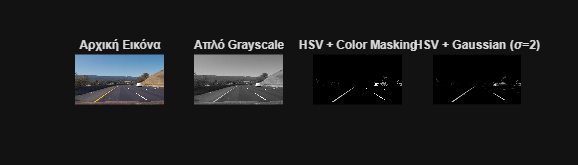



%% Αξιολόγηση Μέρους Α: Οπτική Σύγκριση Μεθόδων
% 1. Απλή Grayscale 
simple_gray = rgb2gray(img);

% 2. HSV + Συνδυασμός Καναλιών [cite: 29, 33]
hsv_test = rgb2hsv(img);
y_mask = (hsv_test(:,:,1) < 0.15) & (hsv_test(:,:,2) > 0.4);
w_mask = (hsv_test(:,:,3) > 0.8) & (hsv_test(:,:,2) < 0.2);
comb_mask = y_mask | w_mask;
advanced_gray = simple_gray;
advanced_gray(~comb_mask) = 0;

% 3. Φίλτρα Εξομάλυνσης στην Advanced Εικόνα
gauss_test = imgaussfilt(advanced_gray, 2);
median_test = medfilt2(advanced_gray, [5 5]);

figure('Name', 'Σύγκριση Μεθόδων Προεπεξεργασίας', 'Position', [100, 100, 1400, 400]);
subplot(1, 4, 1); imshow(img); title('Αρχική Εικόνα');
subplot(1, 4, 2); imshow(simple_gray); title('Απλό Grayscale');
subplot(1, 4, 3); imshow(advanced_gray); title('HSV + Color Masking');
subplot(1, 4, 4); imshow(gauss_test); title('HSV + Gaussian (\sigma=2)');

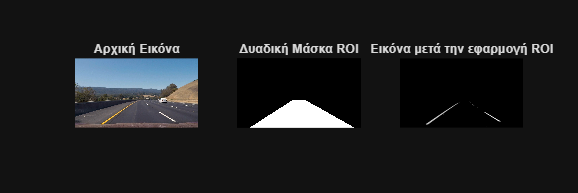


%% Εκτέλεση Μέρους Β: Οπτικοποίηση Περιοχής Ενδιαφέροντος (ROI)
% (Υπολογίζουμε ξανά τη μάσκα εδώ για την οπτικοποίηση στο main)
[rows, cols] = size(gauss_test);
roi_x = [cols*0.1, cols*0.95, cols*0.55, cols*0.45];
roi_y = [rows, rows, rows*0.6, rows*0.6];
roi_mask_test = poly2mask(roi_x, roi_y, rows, cols);

roi_test_img = gauss_test;
roi_test_img(~roi_mask_test) = 0;

figure('Name', 'Εφαρμογή ROI', 'Position', [150, 150, 1200, 400]);
subplot(1, 3, 1); imshow(img); title('Αρχική Εικόνα');
subplot(1, 3, 2); imshow(roi_mask_test); title('Δυαδική Μάσκα ROI');
subplot(1, 3, 3); imshow(roi_test_img); title('Εικόνα μετά την εφαρμογή ROI');

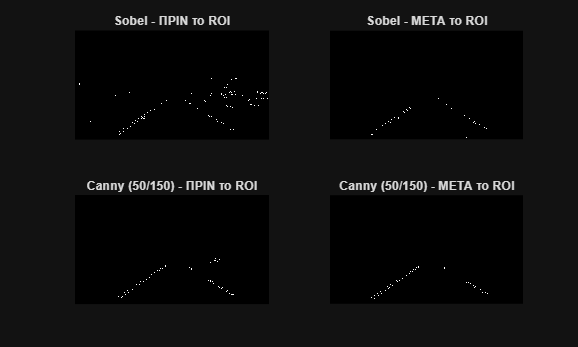


%% Εκτέλεση Μέρους Γ: Οπτικοποίηση και Αξιολόγηση Ακμών
% Sobel και Canny ΠΡΙΝ και ΜΕΤΑ το ROI

% Ανίχνευση Canny (χρησιμοποιούμε την gauss_test που είναι η εικόνα πριν το ROI)
canny_before = edge(gauss_test, 'canny', [50/255, 150/255]);
canny_after = edge(roi_test_img, 'canny', [50/255, 150/255]);

% Ανίχνευση Sobel (το Matlab υπολογίζει αυτόματα το βέλτιστο κατώφλι αν δεν του δώσουμε)
sobel_before = edge(gauss_test, 'sobel');
sobel_after = edge(roi_test_img, 'sobel');

% Γράφημα 1: Σύγκριση Μεθόδων Πριν και Μετά
figure('Name', 'Γ.1 & Γ.2 - Sobel vs Canny (Πριν & Μετά το ROI)', 'Position', [100, 100, 1000, 600]);
subplot(2, 2, 1); imshow(sobel_before); title('Sobel - ΠΡΙΝ το ROI');
subplot(2, 2, 2); imshow(sobel_after); title('Sobel - ΜΕΤΑ το ROI');
subplot(2, 2, 3); imshow(canny_before); title('Canny (50/150) - ΠΡΙΝ το ROI');
subplot(2, 2, 4); imshow(canny_after); title('Canny (50/150) - ΜΕΤΑ το ROI');

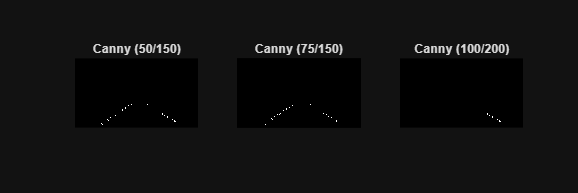


% Πειραματισμός με κατώφλια Canny
canny_75_150 = edge(roi_test_img, 'canny', [75/255, 150/255]);
canny_100_200 = edge(roi_test_img, 'canny', [100/255, 200/255]);

% Γράφημα 2: Σύγκριση Κατωφλίων Canny
figure('Name', 'Γ.3 - Πειραματισμός με Κατώφλια Canny', 'Position', [150, 150, 1200, 400]);
subplot(1, 3, 1); imshow(canny_after); title('Canny (50/150)');
subplot(1, 3, 2); imshow(canny_75_150); title('Canny (75/150)');
subplot(1, 3, 3); imshow(canny_100_200); title('Canny (100/200)');

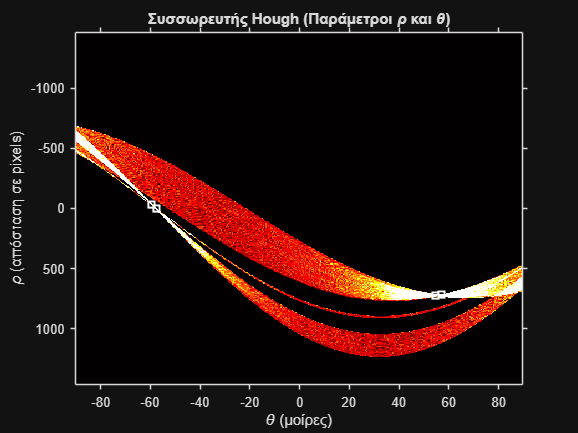


%% Εκτέλεση Μέρους Δ: Οπτικοποίηση Συσσωρευτή Hough
% Υπολογίζουμε ξανά τον μετασχηματισμό για την εικόνα canny_after
[H_test, T_test, R_test] = hough(canny_after, 'RhoResolution', 1, 'Theta', -90:0.5:89.5);
P_test = houghpeaks(H_test, 15, 'threshold', ceil(0.3*max(H_test(:))));

% Εμφάνιση του πίνακα ψήφων (Accumulator)
figure('Name', 'Δ.2 - Συσσωρευτής Hough', 'Position', [150, 150, 800, 600]);
imshow(imadjust(rescale(H_test)), 'XData', T_test, 'YData', R_test, 'InitialMagnification', 'fit');
title('Συσσωρευτής Hough (Παράμετροι \rho και \theta)');
xlabel('\theta (μοίρες)');
ylabel('\rho (απόσταση σε pixels)');
axis on; axis normal; hold on;
colormap(gca, hot);

% Σχεδίαση των κορυφών (peaks) πάνω στον συσσωρευτή με λευκά τετράγωνα
x_peaks = T_test(P_test(:,2)); 
y_peaks = R_test(P_test(:,1));
plot(x_peaks, y_peaks, 's', 'color', 'white', 'LineWidth', 2);
hold off;


%% Εκτέλεση Μέρους ΣΤ: Αξιολόγηση σε υποβαθμισμένες εικόνες
% 1. Προσθήκη θορύβου
img_gaussian_noise = imnoise(img, 'gaussian', 0, 0.02);
img_sp_noise = imnoise(img, 'salt & pepper', 0.05);

% --- Σύγκριση για GAUSSIAN Θόρυβο ---
figure('Name', 'ΣΤ.2 - Σύγκριση Φίλτρων σε Gaussian Θόρυβο', 'Position', [50, 150, 1500, 400]);

subplot(1, 3, 1); 
fprintf('--- Gaussian Θόρυβος ---\n');

--- Gaussian Θόρυβος ---


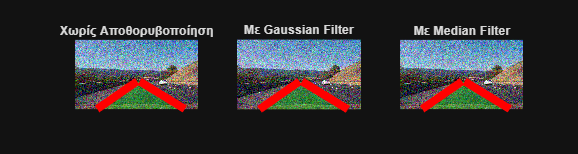

lane_detection_pipeline(img_gaussian_noise, 'none');
title('Χωρίς Αποθορυβοποίηση');

subplot(1, 3, 2); 
lane_detection_pipeline(img_gaussian_noise, 'gaussian');
title('Με Gaussian Filter');

subplot(1, 3, 3); 
lane_detection_pipeline(img_gaussian_noise, 'median');
title('Με Median Filter');


% --- Σύγκριση για SALT & PEPPER Θόρυβο ---
figure('Name', 'ΣΤ.3 - Σύγκριση Φίλτρων σε Salt & Pepper Θόρυβο', 'Position', [100, 100, 1500, 400]);

subplot(1, 3, 1); 
fprintf('--- Salt & Pepper ---\n');

--- Salt & Pepper ---


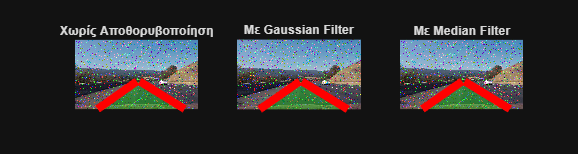

lane_detection_pipeline(img_sp_noise, 'none');
title('Χωρίς Αποθορυβοποίηση');

subplot(1, 3, 2); 
lane_detection_pipeline(img_sp_noise, 'gaussian');
title('Με Gaussian Filter');

subplot(1, 3, 3); 
lane_detection_pipeline(img_sp_noise, 'median');
title('Με Median Filter');